# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

% Clear all the function data as they contain some persistent variables
clear;
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset getTrParamsforSpecificBS_id;
close all;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 1;              % number of online data BS 
overAllOfdmParams.FFTLength               = 256;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.Subcarrierspacing       = 30e3;               % Sub-carrier spacing of 30 KHz
total_RB                                  = 17;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可

% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


## Initialize Receiver Parameters

channelmapping         = 1;  % mutichannel or single channel selection
watch_filteredResult   = false;

% 确定内存读取文件，该文件存放着接收数据的缓存
root = "E:\FDRAN_Prototype\cache_file\";
filename = root + "received_buffer_new.bin";
% 指定从缓存中要处理的起始帧位置、总处理帧数or总处理时间
startframeNum = 1;   
% 是否根据给定时间传输or指定总帧数传输。若为false，则指定帧数传输。
% 在本程序：从内存中读取数据进行后续信号处理解调中，默认为false，即指定处理的帧数
enable_time_limit_transmission = false;
numFrames4process = 2000;    % enable_time_limit_transmission为false生效，则总共处理本变量长度的帧数
rcvtime4process = 10;        % enable_time_limit_transmission为true生效，则总共处理本指定时间长度的帧数
% cfg 用来配置是否进行burst传输、CFO、CPE、信道均衡操作，显示示波器，可视化计算结果等。
cfg.enableBurstMode      = false;                    % 是否选择进行突发接收（适当的采用burst传输以避免overflow，true表示启用burst传输，不是实时的，False表示禁用burst传输，是实时的）
cfg.burstbuffersize      = 30;   % （只有当enableBurstMode为Ture才有效）设定突发传输的buffer大小（一个buffer的总帧数）,

cfg.enableCFO            = true;
cfg.enableCPE            = true;
cfg.enableChest          = true;
cfg.enableHeaderCRCcheck = true;

cfg.enableTimescope      = false;
cfg.enableScopes         = true;
cfg.verbosity            = false;
cfg.printData            = false;
cfg.enableConst_measure  = true;

% 接下来是针对UE B210联合分别接收不同基站数据的radio设置和具体接收算法流程+resource OFDM parameters
overAllOfdmParams.Rcv_DL_CoopBSs_id                   = [1];                %当前服务该用户的下行基站协作集, 接收BS id信号处理的顺序与list前后顺序一致
overAllOfdmParams.PilotSubcarrierSpacing              = [36];              % Pilot sub-carrier spacing
overAllOfdmParams.BWPoffset                           = [0];                %当前基站的总带宽offset（单位/1个子载波），offset设置的是实际带宽start位置相对于初始计算的start的位置的偏移
UE_id                                                 = 1;                    %当前UE的ID标识符
% 根据全局configure和特定配置，初始化所有接收下行基站的 sysParam、rxObj、OFDMParams、dataParams等参数保存至sysParamRxObj
sysParamRxObj = setupSysParamsAndRxObjects(overAllOfdmParams, cfg);
% 检查 sysParamRxObj 中所有基站的 field names和预先确定的overAllOfdmParams中协作基站集ID名称和顺序是否一致
BS_fieldnames = fieldnames(sysParamRxObj);

% read_savedData = false %from bbr()
% if read_savedData
%     radioDevice            = "B210";   % Choose radio device for reception
%     centerFrequency        = 2.2e9;
%     gain                   = 55; % Set radio gain
%     read_filename = 'received_buffer.bb'; 
%     % 初始化接收机USRP radio和软接收object basbandreceiver bbr
%     radio = GetRxUsrpRadioObj(sysParamRxObj,radioDevice,centerFrequency,gain,channelmapping,read_savedData,read_filename);
% end

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

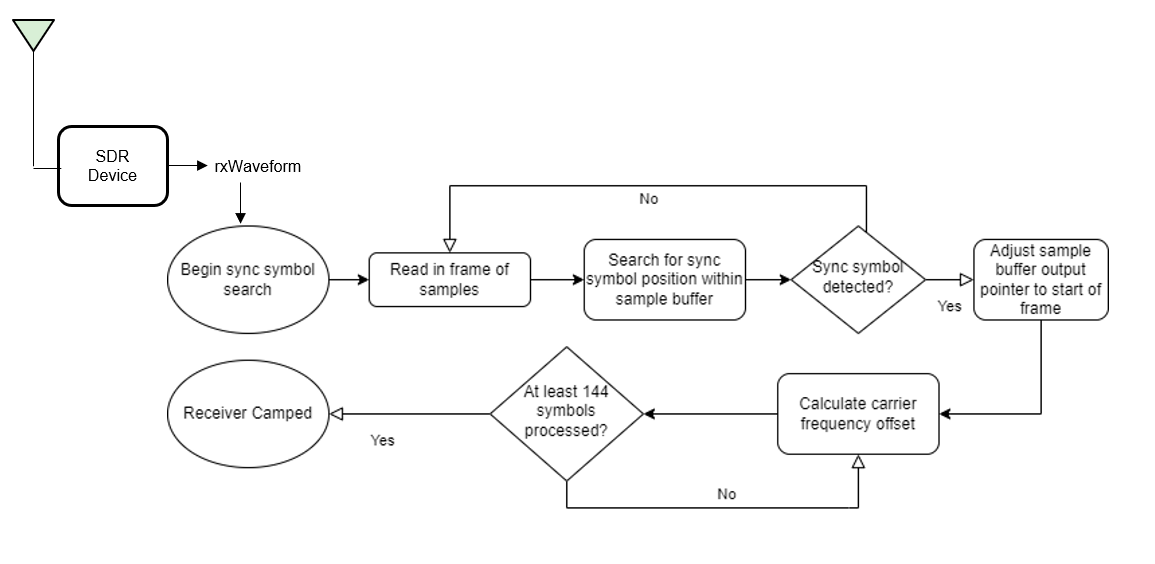

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

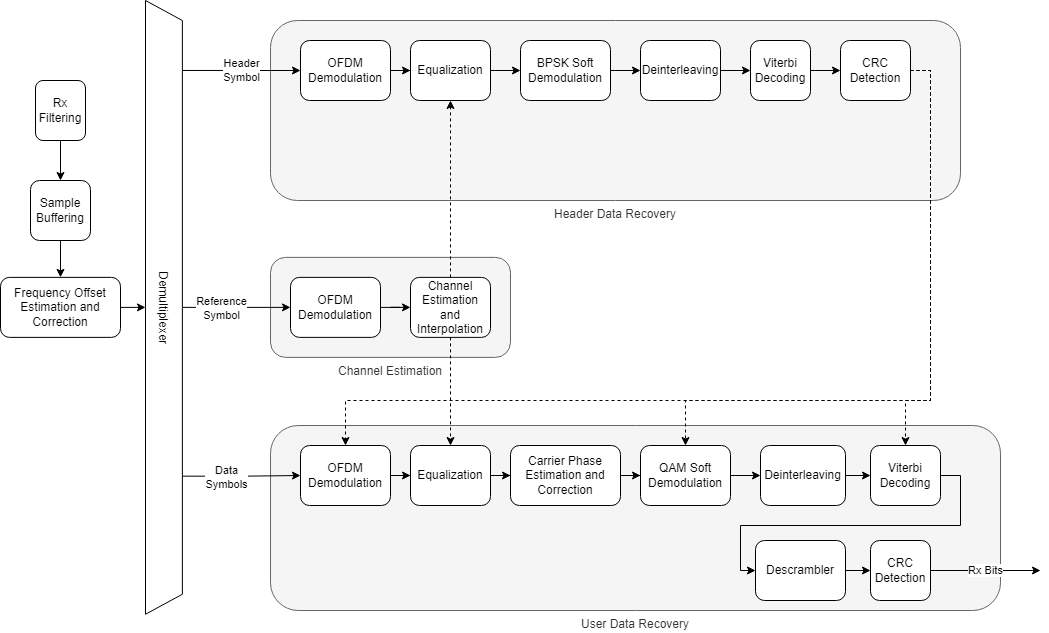

% 初始化所有基站的可视化工具
visualizationTools = setupVisualizationTools(sysParamRxObj);

% 初始化误码率对象和测量结果存储
errorRate_collection = struct();  
BER_collection = struct();
EVM_collection = struct();
MER_collection = struct();
RSSI_collection = struct();
CFO_collection = struct();
isConnected = false;

% 初始化变量用于计算速率
totalBitsReceivedPerBS = zeros(1, length(BS_fieldnames));    % 每个基站每帧接收到的总比特数
previousTimePerBS = struct();                           % 记录每个基站计算速率的起始时间
currentTimePerBS = struct();                            % 记录每个基站计算速率的终了时间
dataRateCollection = struct();                          % 保存每个基站和总的速率
peakRatePerBS = zeros(1, length(BS_fieldnames));        % 每个基站的峰值速率

% 确定接收缓存参数
totalMemorySizeInGB = 4;  % 4GB
totalMemorySizeInBytes = totalMemorySizeInGB * (1024^3);  % 4GB in bytes

% 获取帧大小和采样率
framesize = sysParamRxObj.(current_BS_field).sysParam.txWaveformSize;
samplerate = sysParamRxObj.(current_BS_field).sysParam.SampleRate;
timePerFrame = framesize / samplerate; 

% 定义接收缓存内存映射文件的结构
% 定义结构化message，通过报头报文管理内存空间数据字段。
% Each message will have a header flag (int32) and data (double array)
headerSize = 4;  % bytes for int32
dataSizePerMessage = framesize * 16;  % framesize samples * 16 bytes per complex double sample
bytesPerMessage = headerSize + dataSizePerMessage;
totalMessages = floor(totalMemorySizeInBytes / bytesPerMessage);

% 确定当前buffer能缓存的最大总帧数和接收时间。实际上maxRcvFrames等价于totalMessages
[maxRcvFrames, maxRcvTime] = calculateTotalFramesAndTime(totalMessages, framesize, samplerate);

% 添加选择接收模式的变量，注意：使用debug调试模式时建议使用false
continuousReception = true;  % true 表示持续处理，false 表示接收指定长度

if continuousReception
    % 持续信号处理模式，不指定 numFrame 或 rcvtime，不指定startframeNum
    maxFrames = totalMessages;  % 缓冲区能容纳的最大帧数
    disp('***************Enable continous processing!***************')
    fprintf('buffer能储存的最大总帧数：%d \n', maxRcvFrames);
    fprintf('buffer能储存的最大总接收时间：%.2f 秒 \n', maxRcvTime);
    % 预计算索引列表（对于最大可能的帧数）
    startIdxList = zeros(totalMessages, 1);  % 存储每帧的 dataStartIdx
    endIdxList = zeros(totalMessages, 1);    % 存储每帧的 dataEndIdx
    for i = 1:totalMessages
        startIdxList(i) = (i - 1) * framesize + 1;
        endIdxList(i) = i * framesize;
    end
else
    % 指定处理时间或帧数，Debug调试时使用此选项
    disp('***************Enable desired limit length processing!***************')
    enable_time_limit_transmission = true; % 是否根据给定时间传输。若为false，则指定帧数传输
    if enable_time_limit_transmission
        %指定要进行信号处理的总时间
        rcvtime_n = rcvtime4process;       % units: seconds
        numFrames_n = floor(rcvtime_n/timePerFrame);
    else
        %指定要进行信号处理的总帧数
        numFrames_n = numFrames4process;      
    end

    totalTime = numFrames_n * timePerFrame;
    fprintf('buffer能接收的最大总帧数：%d \n /当前指定接收总帧数: %d\n', maxRcvFrames, numFrames_n);
    fprintf('buffer能接收的最大总接收时间：%.2f 秒 \n / 当前指定总接收时间: %.2f 秒\n', maxRcvTime, totalTime);
    if numFrames_n > maxRcvFrames
        error('set received total frame length (%d) exceeds max length of buffer (%d) for receiving!',numFrames_n,maxRcvFrames)
    end
    if totalTime > maxRcvTime
        error('set received total time (%.3f) exceeds max time length of buffer (%.3f) for receiving!',totalTime,maxRcvTime)
    end
    maxFrames = numFrames_n;
    % 设置从第几帧开始处理数据
    startFrame_n = startframeNum;  % 从第500帧开始
    if startFrame_n < 1
        error('Invalid startFrame: must be greater than or equal to 1.');
    end
    
    if startFrame_n + maxFrames - 1 > maxRcvFrames
        error('The combination of startFrame and numFrames exceeds the buffer capacity.');
    end
    
    % 提前计算从startFrame开始的每帧的开始和结束索引
    startIdxList = ((startFrame_n-1):(startFrame_n+maxFrames-2)) * framesize + 1;
    endIdxList = startIdxList + framesize - 1;
end

% 使用 memmapfile 进行内存映射
% Map the file with the new structure
m = memmapfile(filename, ...
    'Format', { ...
        'int32', [totalMessages, 1], 'headerFlags'; ...
        'double', [totalMessages * framesize, 2], 'complexData' ...
    }, ...
    'Writable', true);

% 初始化中断当前接收状态的共享文件（存储 中断flag 用）
flagFile = 'interrupt_process_flag.bin';

% 如果文件不存在，初始化并写入默认 flag 值
if ~isfile(flagFile)
    fid = fopen(flagFile, 'w');
    fwrite(fid, 1, 'int32');  % 初始化 flag 为 1，表示继续运行
    fclose(fid);
end

% 创建内存映射文件对象
m_ctlflag = memmapfile(flagFile, 'Writable', true, 'Format', 'int32');

% flag置为1表示开始持续性接收
m_ctlflag.Data(1) = 1;

% 初始化每个基站的测量结果存储, 初始化保存每个基站每帧BER、EVM、MER、RSSI、est CFO的结构体
for index = 1:length(BS_fieldnames)
    current_BS_field = BS_fieldnames{index};
    errorRate_collection.(current_BS_field) = comm.ErrorRate(); % 结构体保存每个基站的误码率对象
    dataRateCollection.(current_BS_field) = [];                 % 用于保存每帧速率
    BER_collection.(current_BS_field) = [];
    RSSI_collection.(current_BS_field) = [];
    EVM_collection.(current_BS_field).header = [];
    EVM_collection.(current_BS_field).data = [];
    MER_collection.(current_BS_field).header = [];
    MER_collection.(current_BS_field).data = [];
    CFO_collection.(current_BS_field) = [];                     % 用于保存每帧 CFO 估计值
end
dataRateCollection.total = [];  % 总速率

% 开始持续处理
fprintf('按回车键开始信号处理...');
input('');

if continuousReception
    disp('开始持续信号处理... 运行stop_processing.m来终止持续性信号处理。');
    % 初始化处理指针
    processPointer = 1;
    while m_ctlflag.Data
        % 获取当前消息索引
        messageIndex = processPointer;
    
        % 检查 headerFlag 是否为 0，表示数据已准备好且尚未被处理
        if m.Data.headerFlags(messageIndex) == 0
            % [rxWaveform, ~, overflow] = radio();  % 从无线电设备中读取数据
            % 从内存映射文件中读取指定帧的数据
            startIdx = startIdxList(messageIndex);
            endIdx = endIdxList(messageIndex);
        
            % 读取并重构为复数信号
            rxWaveform = complex(m.Data.complexData(startIdx:endIdx, 1), m.Data.complexData(startIdx:endIdx, 2));
        
            % % 生成 rxWaveform 的多个副本，数量为基站数量
            % rxWaveformCopies = cell(1, length(BS_fieldnames));
            % for i = 1:length(BS_fieldnames)
            %     rxWaveformCopies{i} = rxWaveform;  % 为每个基站生成副本
            % end
        
            if isConnected && cfg.verbosity
                fprintf('____________________________________________________________________________\n')
            end

            % 遍历协作基站集
            for index = 1:length(BS_fieldnames)
                % 获取对应基站的部分参数用于后续计算
                current_BS_field = BS_fieldnames{index};
                transportBlk_bs = sysParamRxObj.(current_BS_field).transportBlk_bs;
            
                % 从副本中获取当前基站对应的 rxWaveform
                rxWaveform_copies_4currentBS = rxWaveform;
                % rxWaveform_copies_4currentBS = rxWaveformCopies{index};
                
                % 运行接收前端
                rxIn = helperOFDMRxFrontEnd(rxWaveform_copies_4currentBS, ...
                    sysParamRxObj.(current_BS_field).sysParam, ...
                    sysParamRxObj.(current_BS_field).rxObj, ...
                    visualizationTools.(current_BS_field).spectrumAnalyze, ...
                    watch_filteredResult);
        
                % 运行接收处理
                previousTimePerBS.(current_BS_field) = tic;
                [rxDataBits, isConnected, toff, rxDiagnostics, SigOccured_frameNum] = helperOFDMRx(rxIn, ...
                    sysParamRxObj.(current_BS_field).sysParam, ...
                    sysParamRxObj.(current_BS_field).rxObj, ...
                    visualizationTools.(current_BS_field).timesink, messageIndex);
                currentTimePerBS.(current_BS_field) = toc(previousTimePerBS.(current_BS_field));
                sysParamRxObj.(current_BS_field).sysParam.timingAdvance = toff;
        
                % 收集误码率和帧错误统计
                if isConnected
                    % 更新误码率
                    berVals_bs = errorRate_collection.(current_BS_field)(transportBlk_bs((1:sysParamRxObj.(current_BS_field).sysParam.trBlkSize)).', rxDataBits);
                    BER_collection.(current_BS_field)(end+1) = berVals_bs(1);
                    totalBitsReceivedPerBS(index) = length(rxDataBits);
        
                    if sysParamRxObj.(current_BS_field).dataParams.printData
                        % 打印接收到的数据
                        numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits), 7);
                        recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode), 7, []), 7));
                        fprintf('[%s]Received data in frame %d from %s: %s\n', current_BS_field, messageIndex, current_BS_field, recData);
                    end
            
                    % 计算数据速率（比特每秒）
                    dataRate = totalBitsReceivedPerBS(index) / currentTimePerBS.(current_BS_field);  % bps
                    
                    % 更新当前基站的峰值速率
                    if dataRate > peakRatePerBS(index)
                        peakRatePerBS(index) = dataRate;
                    end
        
                    % 保存当前的数据速率
                    dataRateCollection.(current_BS_field)(end+1) = dataRate;
        
                end
        
                % 计算 RSSI
                if sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
                    RSSI_collection.(current_BS_field)(end+1) = 10 * log10(mean(abs(rxWaveform_copies_4currentBS).^2)) + 30;  % 计算 dBm 值
                    CFO_collection.(current_BS_field)(end+1) = rxDiagnostics.estCFO(end);  % 记录每帧最后的 CFO 值        
                end
        
                % 计算 EVM 和 MER
                if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
                    % 计算并保存每帧的 EVM、MER和RSSI
                    EVM_collection.(current_BS_field).header(end+1) = visualizationTools.(current_BS_field).constellation_measure.evm_header( ...
                        complex(rxDiagnostics.rxConstellationHeader(:)));
                    EVM_collection.(current_BS_field).data(end+1) = visualizationTools.(current_BS_field).constellation_measure.evm_data( ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                    MER_collection.(current_BS_field).header(end+1) = visualizationTools.(current_BS_field).constellation_measure.mer_header( ...
                        complex(rxDiagnostics.rxConstellationHeader(:)));
                    MER_collection.(current_BS_field).data(end+1) = visualizationTools.(current_BS_field).constellation_measure.mer_data( ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                end
        
                % 显示星座图
                if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableScopes
                    visualizationTools.(current_BS_field).constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), complex(rxDiagnostics.rxConstellationData(:)));
                end  
            end
            % 计算当前帧下联合接收所有基站的总速率,计算联合速率 (bps)
            totalBitsReceived = sum(totalBitsReceivedPerBS);  % 所有基站的总比特数
            totaltime = sum(struct2array(currentTimePerBS));  % 总时间
            totalDataRate = totalBitsReceived / totaltime;
            dataRateCollection.total(end+1) = totalDataRate;
        
            % 将 headerFlag 设置为 1（表示数据已处理）
            m.Data.headerFlags(messageIndex) = 1;
        
            % 显示频谱分析
            if sysParamRxObj.(current_BS_field).dataParams.enableScopes && ~watch_filteredResult
                visualizationTools.(current_BS_field).spectrumAnalyze.Title = 'Received Signal from ALL Downlink BSs';
                visualizationTools.(current_BS_field).spectrumAnalyze(rxWaveform);
            end

            % 增加处理指针，循环缓冲区
            processPointer = processPointer + 1;
            if processPointer > totalMessages
                processPointer = 1;
            end
        else
            % 如果 headerFlag 为 1，表示重复处理之前处理过的数据，即数据未准备好或已被处理
            error('Data at messageIndex %d has already been processed, new data is not ready.', messageIndex);
        end
    end
    disp('检测到中断信号，停止信号处理。');
    
else
    fprintf('开始指定长度：(%d帧, %.2f秒)信号处理...', maxFrames, totalTime)
    for frameNum = 1:maxFrames
        % 检查 headerFlag 是否为 0，表示数据已准备好且尚未被处理
        if m.Data.headerFlags(frameNum+startFrame_n-1) == 0
            % [rxWaveform, ~, overflow] = radio();  % 从无线电设备中读取数据
            % 从内存映射文件中读取指定帧的数据
            startIdx = startIdxList(frameNum);
            endIdx = endIdxList(frameNum);
        
            % 读取并重构为复数信号
            rxWaveform = complex(m.Data.complexData(startIdx:endIdx, 1), m.Data.complexData(startIdx:endIdx, 2));
        
            % % 生成 rxWaveform 的多个副本，数量为基站数量
            % rxWaveformCopies = cell(1, length(BS_fieldnames));
            % for i = 1:length(BS_fieldnames)
            %     rxWaveformCopies{i} = rxWaveform;  % 为每个基站生成副本
            % end
        
            if isConnected && cfg.verbosity
                fprintf('____________________________________________________________________________\n')
            end
        
        
            % 遍历协作基站集
            for index = 1:length(BS_fieldnames)
                % 获取对应基站的部分参数用于后续计算
                current_BS_field = BS_fieldnames{index};
                transportBlk_bs = sysParamRxObj.(current_BS_field).transportBlk_bs;
            
                % 从副本中获取当前基站对应的 rxWaveform
                rxWaveform_copies_4currentBS = rxWaveform;
                % rxWaveform_copies_4currentBS = rxWaveformCopies{index};
                
                % 运行接收前端
                rxIn = helperOFDMRxFrontEnd(rxWaveform_copies_4currentBS, ...
                    sysParamRxObj.(current_BS_field).sysParam, ...
                    sysParamRxObj.(current_BS_field).rxObj, ...
                    visualizationTools.(current_BS_field).spectrumAnalyze, ...
                    watch_filteredResult);
        
                % 运行接收处理
                previousTimePerBS.(current_BS_field) = tic;
                [rxDataBits, isConnected, toff, rxDiagnostics, SigOccured_frameNum] = helperOFDMRx(rxIn, ...
                    sysParamRxObj.(current_BS_field).sysParam, ...
                    sysParamRxObj.(current_BS_field).rxObj, ...
                    visualizationTools.(current_BS_field).timesink, frameNum);
                currentTimePerBS.(current_BS_field) = toc(previousTimePerBS.(current_BS_field));
                sysParamRxObj.(current_BS_field).sysParam.timingAdvance = toff;
        
                % 收集误码率和帧错误统计
                if isConnected
                    % 更新误码率
                    berVals_bs = errorRate_collection.(current_BS_field)(transportBlk_bs((1:sysParamRxObj.(current_BS_field).sysParam.trBlkSize)).', rxDataBits);
                    BER_collection.(current_BS_field)(frameNum) = berVals_bs(1);
                    totalBitsReceivedPerBS(index) = length(rxDataBits);
        
                    if sysParamRxObj.(current_BS_field).dataParams.printData
                        % 打印接收到的数据
                        numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits), 7);
                        recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode), 7, []), 7));
                        fprintf('[%s]Received data in frame %d from %s: %s\n', current_BS_field, frameNum, current_BS_field, recData);
                    end
            
                    % 计算数据速率（比特每秒）
                    dataRate = totalBitsReceivedPerBS(index) / currentTimePerBS.(current_BS_field);  % bps
                    
                    % 更新当前基站的峰值速率
                    if dataRate > peakRatePerBS(index)
                        peakRatePerBS(index) = dataRate;
                    end
        
                    % 保存当前的数据速率
                    dataRateCollection.(current_BS_field)(frameNum) = dataRate;
        
                end
        
                % 计算 RSSI
                if sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
                    RSSI_collection.(current_BS_field)(frameNum) = 10 * log10(mean(abs(rxWaveform_copies_4currentBS).^2)) + 30;  % 计算 dBm 值
                    CFO_collection.(current_BS_field)(frameNum) = rxDiagnostics.estCFO(end);  % 记录每帧最后的 CFO 值        
                end
        
                % 计算 EVM 和 MER
                if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
                    % 计算并保存每帧的 EVM、MER和RSSI
                    EVM_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_header( ...
                        complex(rxDiagnostics.rxConstellationHeader(:)));
                    EVM_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_data( ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                    MER_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_header( ...
                        complex(rxDiagnostics.rxConstellationHeader(:)));
                    MER_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_data( ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                end
        
                % 显示星座图
                if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableScopes
                    visualizationTools.(current_BS_field).constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), complex(rxDiagnostics.rxConstellationData(:)));
                end  
            end
            % 计算当前帧下联合接收所有基站的总速率,计算联合速率 (bps)
            totalBitsReceived = sum(totalBitsReceivedPerBS);  % 所有基站的总比特数
            totaltime = sum(struct2array(currentTimePerBS));  % 总时间
            totalDataRate = totalBitsReceived / totaltime;
            dataRateCollection.total(frameNum) = totalDataRate;
        
            % 将 headerFlag 设置为 1（表示数据已处理）
            m.Data.headerFlags(frameNum) = 1;
        
            % 显示频谱分析
            if sysParamRxObj.(current_BS_field).dataParams.enableScopes && ~watch_filteredResult
                visualizationTools.(current_BS_field).spectrumAnalyze.Title = 'Received Signal from ALL Downlink BSs';
                visualizationTools.(current_BS_field).spectrumAnalyze(rxWaveform);
            end
        else
            % 如果 headerFlag 为 1，表示重复处理之前处理过的数据，即数据未准备好或已被处理
            error('Data at messageIndex %d has already been processed, new data is not ready.', frameNum+startFrame_n-1);
        end
    end

end

disp('Start Plotting ...')
% 主循环结束后绘图
plotDataRates(BS_fieldnames, dataRateCollection, maxFrames);
plotRSSI(BS_fieldnames, RSSI_collection, maxFrames);
plotEVMandMER(BS_fieldnames, EVM_collection, MER_collection, maxFrames);
plotCFO(BS_fieldnames, CFO_collection, maxFrames);  % 新增绘制 CFO 的函数
disp('Plotting complete!')

% 显示每个基站的平均 BER 值和 EVM、MER 测量结果
for index = 1:length(BS_fieldnames)
    current_BS_field = BS_fieldnames{index};
    Length = length(current_BS_field);          % 用于输出对齐
        
    avg_BER         = mean(BER_collection.(current_BS_field));           % 计算当前基站平均BER
    avgRatePerBS    = mean(dataRateCollection.(current_BS_field));       % 计算当前基站平均速率
    avgRSSI         = mean(RSSI_collection.(current_BS_field));          % 计算当前基站平均RSSI
    
    fprintf('-------measurement-------\n')
    fprintf('%s Measurement:\n', current_BS_field);
    % fprintf('%s Average BER = %.4e\n', current_BS_field, avg_BER);
    fprintf(['%' num2str(Length) 's Average BER = %.4e\n'], '', avg_BER);
    fprintf(['%' num2str(Length) 's Average Data Rate: %.4e bps\n'], '', avgRatePerBS);
    fprintf(['%' num2str(Length) 's Peak Data Rate: %.4e bps\n'], '', peakRatePerBS(index));
    fprintf(['%' num2str(Length) 's Average RSSI: %.4f dBm\n'], '', avgRSSI);

    % 平均 EVM 和 MER
    avg_EVM_header = mean(EVM_collection.(current_BS_field).header);
    avg_EVM_data = mean(EVM_collection.(current_BS_field).data);
    avg_MER_header = mean(MER_collection.(current_BS_field).header);
    avg_MER_data = mean(MER_collection.(current_BS_field).data);

    fprintf(['%' num2str(Length) 's Header rms EVM(%%): %.3f %%\n'], '', avg_EVM_header);
    fprintf(['%' num2str(Length) 's Data rms EVM(%%): %.3f %%\n'], '', avg_EVM_data);
    fprintf(['%' num2str(Length) 's Header MER(dB): %.3f dB\n'], '', avg_MER_header);
    fprintf(['%' num2str(Length) 's Data MER(dB): %.3f dB\n \n'], '', avg_MER_data);
    if index == length(BS_fieldnames)
        % 计算并打印总的平均和峰值速率
        avgTotalRate = mean(dataRateCollection.total);
        peakTotalRate = max(dataRateCollection.total);
        fprintf('Total Average Data Rate: %.4e bps\n', avgTotalRate);
        fprintf('Total Peak Data Rate: %.4e bps\n', peakTotalRate);
    end
end

fprintf(['----------------------------\n' ...
    'Simulation complete!\n' ...
    '----------------------------\n'])

% 释放资源
% release(radio);

%% 调整后的函数，用于计算总帧数和时间
function [totalFrames, totalTime] = calculateTotalFramesAndTime(totalMessages, framesize, samplerate)
    totalFrames = totalMessages;
    timePerFrame = framesize / samplerate;
    totalTime = totalFrames * timePerFrame;
end